clear;clc;

## 读取数据

load("PointOctahedron.mat")
P_bound1 = top_face_transformed(10,:);
P_bound2 = bottom_face_transformed(20,:);
planes = planes';

[PlaneParaOut,TrianglePoints] = planefit8(side_faces_transformed1',side_faces_transformed2',side_faces_transformed3',side_faces_transformed4',side_faces_transformed5',side_faces_transformed6',side_faces_transformed7',side_faces_transformed8',P_bound1,P_bound2);

PlaneParaOut = PlaneParaOut';

% 初始化一个矩阵存储叉乘结果
cross_vectors = zeros(8, 3);

% 计算每对相邻侧面法向量的叉乘
for i = 1:8
    if i < 8
        cross_vectors(i, :) = cross(PlaneParaOut(i, 1:3), PlaneParaOut(i+1, 1:3));
    else
        cross_vectors(i, :) = cross(PlaneParaOut(i, 1:3), PlaneParaOut(1, 1:3)); % 最后一个与第一个相邻
    end
    cross_vectors(i, :) = cross_vectors(i, :) / norm(cross_vectors(i, :)); % 归一化
end

% 使所有方向一致
reference_vector = cross_vectors(1, :);  % 选择第一个向量作为参考
for i = 2:8
    if dot(reference_vector, cross_vectors(i, :)) < 0  % 如果方向相反
        cross_vectors(i, :) = -cross_vectors(i, :);    % 翻转方向
    end
end


% 计算平均方向向量，并归一化
n = mean(cross_vectors, 1);


% 计算顶面方程的 d 值
d_top = -dot(n, P_bound1);

% 计算底面方程的 d 值
d_bottom = -dot(n, P_bound2);

% 初始化顶点矩阵
vertices = zeros(16, 3);

% 计算顶面和底面的8个顶点
for i = 1:8
    % 顶面顶点
    if i < 8
        PlaneParaOut1 = PlaneParaOut(i, :);
        PlaneParaOut2 = PlaneParaOut(i + 1, :);
    else
        PlaneParaOut1 = PlaneParaOut(i, :);
        PlaneParaOut2 = PlaneParaOut(1, :);
    end
    
    % 求顶面和两个相邻侧面的交线
    A = [PlaneParaOut1(1:3); PlaneParaOut2(1:3); n];
    B_top = [-PlaneParaOut1(4); -PlaneParaOut2(4); -d_top];
    vertices(i, :) = A\B_top;

    % 求底面和两个相邻侧面的交线
    B_bottom = [-PlaneParaOut1(4); -PlaneParaOut2(4); -d_bottom];
    vertices(i + 8, :) = A\B_bottom;
end

% 打印或返回结果
disp(vertices);

    0.2277    0.2651    0.7789
   -0.1513    0.2215    0.7535
   -0.3839   -0.0429    0.6005
   -0.3322   -0.3692    0.4118
   -0.0292   -0.5703    0.2958
    0.3506   -0.5269    0.3211
    0.5831   -0.2662    0.4719
    0.5321    0.0635    0.6625
    0.2292    0.7688   -0.0907
   -0.1511    0.7251   -0.1162
   -0.3833    0.4611   -0.2689
   -0.3311    0.1319   -0.4592
   -0.0289   -0.0687   -0.5750
    0.3489   -0.0255   -0.5499
    0.5840    0.2380   -0.3974
    0.5330    0.5676   -0.2069



## 验证

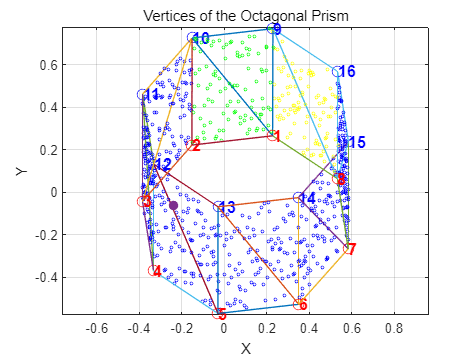

figure
hold on 
box on
grid on
axis equal
scatter3(side_faces_transformed1(:,1),side_faces_transformed1(:,2),side_faces_transformed1(:,3),5,'yellow')
scatter3(side_faces_transformed2(:,1),side_faces_transformed2(:,2),side_faces_transformed2(:,3),5,'green')
scatter3(side_faces_transformed3(:,1),side_faces_transformed3(:,2),side_faces_transformed3(:,3),5,'blue')
scatter3(side_faces_transformed4(:,1),side_faces_transformed4(:,2),side_faces_transformed4(:,3),5,'blue')
scatter3(side_faces_transformed5(:,1),side_faces_transformed5(:,2),side_faces_transformed5(:,3),5,'blue')
scatter3(side_faces_transformed6(:,1),side_faces_transformed6(:,2),side_faces_transformed6(:,3),5,'blue')
scatter3(side_faces_transformed7(:,1),side_faces_transformed7(:,2),side_faces_transformed7(:,3),5,'blue')
scatter3(side_faces_transformed8(:,1),side_faces_transformed8(:,2),side_faces_transformed8(:,3),5,'blue')

% 顶面点
plot3(vertices(1:8, 1), vertices(1:8, 2), vertices(1:8, 3), 'ro', 'MarkerSize', 8, 'DisplayName', 'Top Face Vertices');

% 底面点
plot3(vertices(9:16, 1), vertices(9:16, 2), vertices(9:16, 3), 'bo', 'MarkerSize', 8, 'DisplayName', 'Bottom Face Vertices');

% 标记顶面顶点编号
for i = 1:8
    text(vertices(i, 1), vertices(i, 2), vertices(i, 3), num2str(i), 'Color', 'red', 'FontSize', 12, 'FontWeight', 'bold');
end

% 标记底面顶点编号
for i = 1:8
    text(vertices(i + 8, 1), vertices(i + 8, 2), vertices(i + 8, 3), num2str(i + 8), 'Color', 'blue', 'FontSize', 12, 'FontWeight', 'bold');
end

% 添加图例和标签
% legend('Top Face Vertices', 'Bottom Face Vertices');
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Vertices of the Octagonal Prism');

% 设置视角和网格
grid on;
axis equal;
scatter3(P_bound1(:,1),P_bound1(:,2),P_bound1(:,3),50,'filled')

for i =1:16
    idt = [(i-1)*3+1:i*3,(i-1)*3+1];
    PointTri = TrianglePoints(:,idt);
    plot3(PointTri(1,:),PointTri(2,:),PointTri(3,:));
end

## 参数计算